clear; close all; clc; clf;



%DesignParameters = [a_0, n, sigma_p, gamma_p, cstar, rho_p, mw_air, gamma_air, A_rocket, R_u, ge]
DesignParameters = [0.03,0.35, 0.001, 1.25, 5210, 0.065, 28.97, 1.4, pi*(6.19/24)^2, 1545.3, 32.2];

%DesignInputs = [r_i, r_o, l_0, Ngrain, mystery_0, A_t0, m_bal];

% baseline design
DesignInputs = [1, 2.375, 8, 4, 4, 1, 1];

%DesignOutputs = [m_p0, A_tb, t_b, isp_avg, p_cmax, f_max, A_p0A_t0]
DesignOutputs = [0, 0, 0, 0, 0, 0, 0];



x = thrust_coefficient(1.2,81,10000000000000)

x = 1.9380

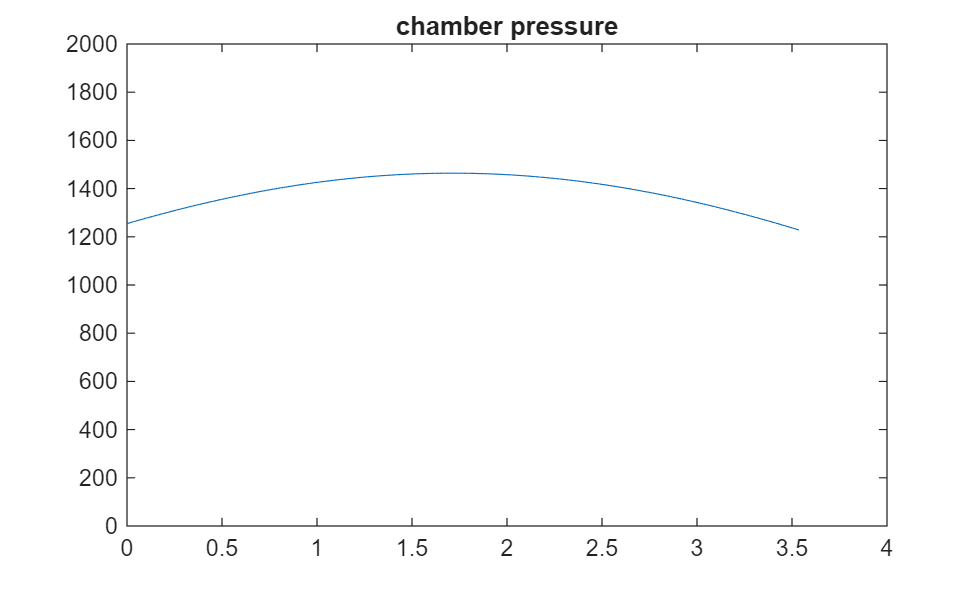

I =          0   53.3793   53.5445   53.7073   53.8676   54.0253   54.1804   54.3331   54.4832   54.6308   54.7759   54.9185   55.0585   55.1960   55.3309   55.4634   55.5933   55.7207   55.8455   55.9678   56.0876   56.2049   56.3197   56.4319   56.5416   56.6487   56.7534   56.8555   56.9550   57.0521   57.1466   57.2386   57.3281   57.4150   57.4994   57.5813   57.6607   57.7375   57.8118   57.8836   57.9528   58.0196   58.0837   58.1454   58.2046   58.2612   58.3152   58.3668   58.4158   58.4623


Isp = 257.8638

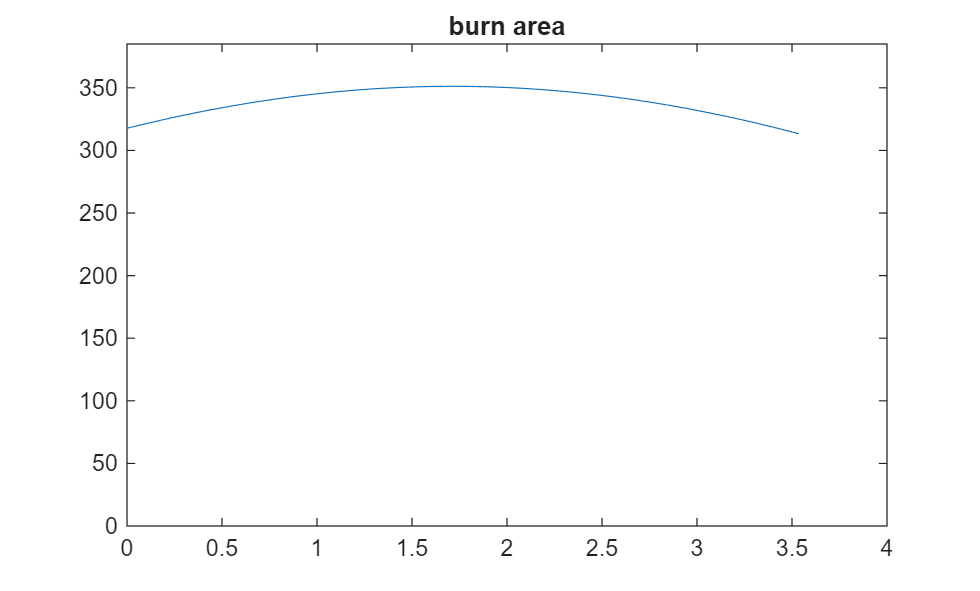

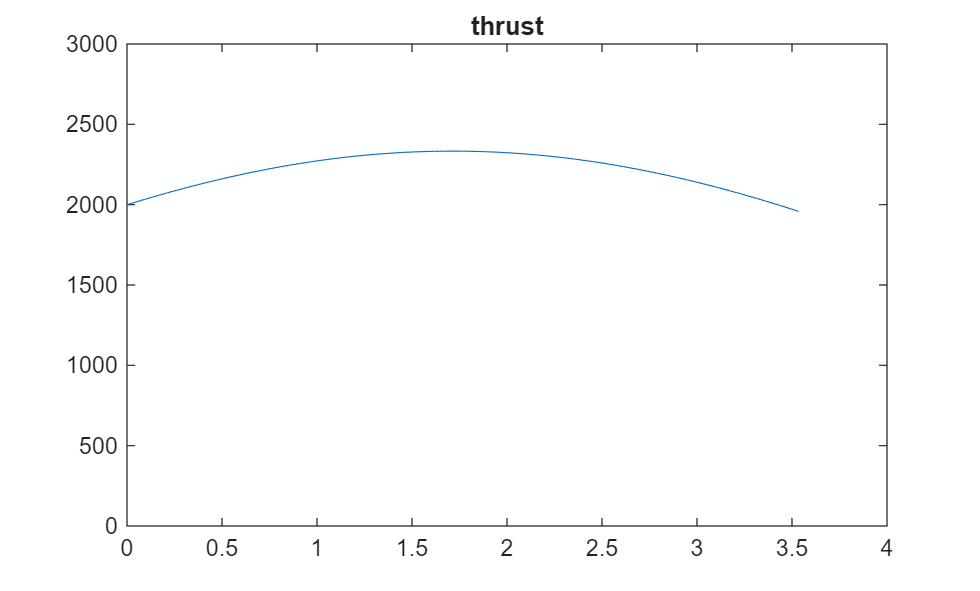

DesignOutputs = 1.0e+03 *

    0.0303
    0.0010
    0.0035
    0.2579
    1.4640
    2.3333
    0.0031
    0.0014
    0.0016




DesignOutputs = rocket(DesignInputs,DesignParameters)






function [DesignOutputs] = rocket(DesignInputs,DesignParameters)

    w_step = 0.01;

    Cd =  [0.15 0.15 0.42 0.25 0.175];
    mCd = [0.00 0.60 1.20 1.80 4.000];

    r_i = DesignInputs(1);
    r_o = DesignInputs(2);
    l_0 = DesignInputs(3);
    Ngrain = DesignInputs(4);
    A_e0 = DesignInputs(5);
    A_t0 = DesignInputs(6);
    m_bal = DesignInputs(7);

    a_0 = DesignParameters(1);
    n = DesignParameters(2);
    sigma_p = DesignParameters(3);
    gamma_p = DesignParameters(4);
    cstar = DesignParameters(5); 
    rho_p = DesignParameters(6);
    mw_air = DesignParameters(7);
    gamma_air = DesignParameters(8);
    A_rocket = DesignParameters(9);
    R_u = DesignParameters(10);
    ge = DesignParameters(11);
    

    
    if (l_0/2) < (r_o - r_i)
        wmax = l_0/2;
    else
        wmax = r_o - r_i;
    end

    w = [0:w_step:wmax wmax];
    
    A_b = Ngrain * pi .* ((r_o^2 - (r_i + w).^2)*2 + ((r_i + w)*2).*(l_0 - 2.* w));
    A_p = pi.*(r_i+w).^2;
    p_c = zeros(size(w)); p_c(1) = (a_0 * exp(sigma_p*(100-70)) * rho_p * A_b(1) * cstar/(ge * A_t0))^(1/(1-n));         
    A_t = zeros(size(w)); A_t(1) = A_t0;     
    r = zeros(size(w)); r(1) = a_0 * exp(sigma_p*(100-70)) * p_c(1)^n;         
    vel = zeros(size(w)); vel(1) = 0;      
    T_a = zeros(size(w)); T_a(1) = 518;     
    
    mdot = zeros(size(w)); mdot(1) = p_c(1)* A_t(1)/cstar;                   
    m_r = zeros(size(w)); m_r(1) = m_bal +    Ngrain * (r_o^2 - r_i^2) * pi * l_0 + (l_0+0.125) * Ngrain * 0.25 + 40;
    rho_air = zeros(size(w)); rho_air(1) = 0.07579;
    mach = zeros(size(w)); mach(1) = 0;
    eta = zeros(size(w)); eta(1) = A_e0/A_t(1);
    acc = zeros(size(w)); acc(1) = 0;
    height = zeros(size(w)); height(1) = 0;
    p_a = ones(size(w)); p_a(1) = 0.0000000000000000000000000000001; %14.69241; 
    m_p = pi.*(r_o^2 - (r_i+w).^2).* rho_p .* (l_0 - 2.*w) .* Ngrain;
    time = zeros(size(w)); 
    F_t = zeros(size(w)); F_t(1) = thrust_coefficient(gamma_p,eta(1),p_c(1)/p_a(1)) * A_t(1) * p_c(1);
    I = zeros(size(w)); 
  
    for i = 1:(length(w)-1)
        
        p_c(i) = (a_0* exp(sigma_p*(100-70)) * rho_p * A_b(i) * cstar/(ge * A_t(i)))^(1/(1-n));
        p_c(end) = (a_0* exp(sigma_p*(100-70)) * rho_p * A_b(end) * cstar/(ge * A_t(end)))^(1/(1-n));

        mdot(i+1) =  p_c(i)* A_t(i)/cstar;

        r(i+1) = a_0 * exp(sigma_p*(100-70)) * p_c(i)^n;

        time(i+1) = time(i) + (w(i+1)-w(i))/r(i+1);

        A_t(i+1) = A_t0; %( (4/pi) ^ 0.5 + 0.000087 * (time(i+1) - time(i)) * p_c(i) )^(2) * pi/4;

        eta(i) = A_e0/A_t(i);

        mach(i+1) = vel(i)/sqrt(gamma_air * R_u/mw_air * T_a(i));

        acc(i+1) = F_t(i)/m_r(i) - ge - interp1(mCd,Cd,mach(i),'linear','extrap') * 0.5 * rho_air(i) * vel(i)^2 * A_rocket/m_r(i);

        vel(i+1) = (acc(i+1) + acc(i))/2 * (time(i+1) - time(i));

        height(i+1) = 0;%(vel(i+1) + vel(i))/2 * (time(i+1) - time(i));

        rho_air(i+1) = 0.00000000001255* height(i)^2 - 0.0000019453*height(i) + 0.07579;

        p_a(i+1) = 0.000000000000000000001; %-4.272981E-14*height(i)^3 + 0.000000008060081*height(i)^2 - 0.0005482655*height(i) + 14.69241; 

        F_t(i) = p_c(i) * A_t(i) * thrust_coefficient(gamma_p,eta(i),p_c(i)/p_a(i));

        cf(i+1) = thrust_coefficient(gamma_p,eta(i),p_c(i)/p_a(i));

        

        T_a(i+1) = -0.0036*height(i) + 518;

        %        balast mass             mass of the grains                         case mass                   baseline mass
        m_r(i+1) = (m_bal +    Ngrain * (r_o^2 - (r_i)^2) * pi * l_0 *rho_p + (l_0+0.125) * Ngrain * 0.25 + 40) - mdot(i)*(time(i+1) - time(i));

        

     
  
    end
  
    

    p_c(end) = (a_0* exp(sigma_p*(100-70)) * rho_p * A_b(end) * cstar/(ge * A_t(end)))^(1/(1-n));
    eta(end) = A_e0/A_t(end);
    F_t(end) = p_c(end) * A_t(end) * thrust_coefficient(gamma_p,eta(end),p_c(end)/p_a(end));

    for i = 1:(length(w)-1)

    I(i+1) = ( F_t(i+1) + F_t(i) )/2 * (time(i+1) - time(i));

    end
   
    I

    I_total = sum(I);
    Isp = I_total/m_p(1)

    
   

    figure(1)
    plot(time,p_c)
    title('chamber pressure')
    ylim([0 2000])
    figure(2)
    plot(time,A_b)
    title('burn area')
    ylim([0 385])
    figure(3)
    plot(time,F_t)
    title('thrust')
    ylim([0 3000])
  

    DesignOutputs = [Ngrain * (r_o^2 - r_i^2) * pi * l_0*rho_p 
        A_t(end)
        time(end)
        Isp
        max(p_c)
        max(F_t)
        A_p(1)/A_t(1)
        max(w)
        mean(cf)];

end


function [cf] = thrust_coefficient(gamma, areaRatio, pcpa)

    f = @(M) (1./M) .* ( (2/(gamma+1)) .* (1 + (gamma-1)/2 .* M.^2) ).^((gamma+1)/(2*(gamma-1))) - areaRatio;
    try
        mach = fzero(f, [1.0001, 50]);
    catch
        mach = fzero(f,[-10 0.99999999]);
   
    end
    papc = 1/pcpa;
    pepc = (1+ (gamma-1)/2 * mach^2 )^(-gamma/(gamma-1));

    one = (2*gamma^2)/(gamma-1);
    two = (2/(gamma+1))^((gamma+1)/(gamma-1));
    three = (1 - pepc^((gamma-1)/gamma));
    four = sqrt(one*two*three);
    five = (pepc-papc)*areaRatio;
    cf = four + five;
end
